**Topics II.4-II.5: Gradient-based and Derivative-free Optimization in Matlab**

Clear the workspace and close any active figure windows

clear all; close all;

Recall our double-valley function $f\left(x_1 ,x_2 \right)=\;2-2x_1 +2x_2 +x_1^2 +x_2^2$. Lets replot it and then try several optimization approaches for finding its roots.

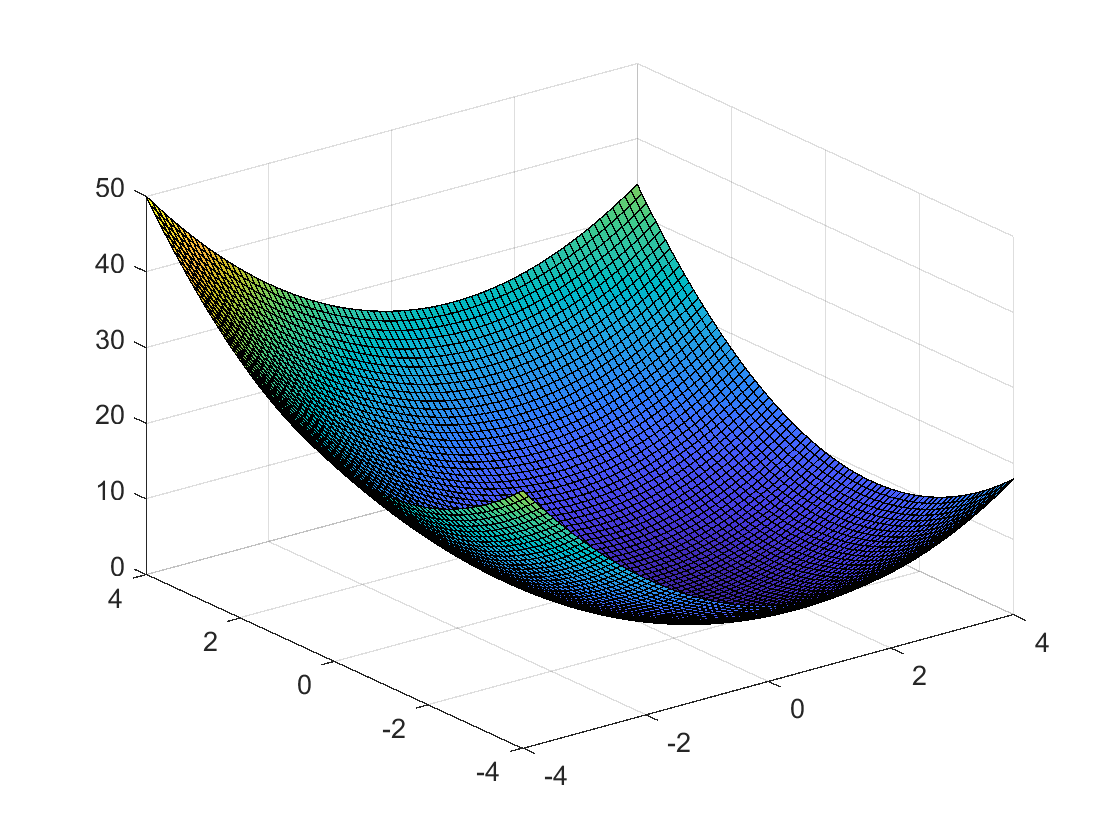

[x1 x2]=meshgrid(-4:0.1:4);
f = 2 - 2*x1 + 2*x2 + x1.^2 + x2.^2;
surf(x1,x2,f)

The exact solution to the equation $\nabla f = \vec{0}$ here is:


$$(x_1^{(1)},x_2^{(1)})=(1,-1)$$


The corresponding function value is:


$$f(x_1^{(1)},x_2^{(1)})=0$$


**A) Newton's Method **

Since this function has an explicit analytical form, we can directly determine its Hessian matrix and the associated inverse. 


$${\bf H}(f)=\left[
\begin{array}{cc}
2 & 0\\
0 & 2
\end{array}
\right]
\Rightarrow
{\bf H}^{-1}(f)=
\left[
\begin{array}{cc}
\frac{1}{2} & 0\\
0 & \frac{1}{2}
\end{array}
\right]$$


Of course, we will also need its gradient:


$$\nabla f = [-2 + 2x_1, 2 + 2x_2]^T$$


Now recall Newton's Method from Topic II.4


$$\vec{x}^{(\tau + 1)} = \vec{x}^{(\tau)}-h_{\tau} \left[{\bf H}(f(\vec{x}^{(\tau)}))\right]^{-1}\nabla f(\vec{x}^{(\tau)})$$


Let's first implement Newton's Method with a fixed step size

NMax=1e5;           % max no. of iterations
x=zeros(2,NMax);    % matrix to store iterations
x(:,1)=[1;1];       % set the initial guess 

h=1e-3;             % set the step size
eps=1e-1;           % tolerance for the gradient
magGrad=1e16;       % initialize magnitude of gradient
i=1;                % initialize counter for iterations

gradF=zeros(2,1);   % vector to store the gradient
invH=zeros(2,2);    % matrix to store the inverse Hessian

while magGrad > eps
    i = i+1;                                
    xx1 = x(1,i-1); xx2 = x(2,i-1);         
    gradF = [-2+2*xx1 ; 2+2*xx2]; % gradient
    invH = [0.5 0; 0 0.5];    % inverse Hessian
    x(:,i) = x(:,i-1) - h*invH*gradF;    % Newton step
    magGrad = norm(gradF,2);             % gradient magnitude
end

error = norm(x(:,i)-[1;-1],2);

SS0=sprintf('\r');
SS1=sprintf('A) Newtons method');
SS2=sprintf('-----------------');
SS3=sprintf('Root approximation is: (x1,x2)=(%f,%f) in %d iterations',x(1,i),x(2,i),i);
SS4=sprintf('The error in the approximation is %e\n',error);
disp(SS0)
disp(SS1)

A) Newtons method


disp(SS2)

-----------------


disp(SS3)

Root approximation is: (x1,x2)=(1.000000,-0.950098) in 3690 iterations


disp(SS4)

The error in the approximation is 4.990178e-02



**B) Unconstrained optimization routine (fminunc)**

SS0=sprintf('\n');
SS1=sprintf('B1) fminunc - no gradient supplied');
SS2=sprintf('----------------------------------');
disp(SS0);
disp(SS1);

B1) fminunc - no gradient supplied


disp(SS2);

----------------------------------


Set the initial guess

xB0=[1,1]; 

Let's first try running the standard algorithm with a quasi-Newton method and showing the iterations

options = optimoptions(@fminunc,'Display','iter','Algorithm','quasi-newton');

Error using optimoptions (line 124)
Invalid solver specified. Provide a solver name or handle (such as 'fmincon' or @fminunc).
Type DOC OPTIMOPTIONS for a list of solvers.

[xBOpt,fDVval,exitflag,output] = fminunc('fDV',xB0,options)

Now evaluate the performance

error = norm(xBOpt-[1,-1],2);

SS3=sprintf('Root approximation is: (x1,x2)=(%f,%f) in %d iterations',xBOpt(1),xBOpt(2),output.iterations);
SS4=sprintf('The error in the approximation is %e\n',error);
disp(SS3)
disp(SS4)

SS0=sprintf('\n');
SS1=sprintf('B2) fminunc - with gradient supplied');
SS2=sprintf('------------------------------------');
disp(SS0)
disp(SS1)
disp(SS2)

When the gradient is available, we can also supply it directly to the optimization routine

options = optimoptions('fminunc','Algorithm','trust-region','SpecifyObjectiveGradient',true);
[xBOpt,fDVval,exitflag,output] = fminunc('fDVwithgrad',xB0,options)

Now evaluate the performance

error = norm(xBOpt-[1,-1],2);

SS3=sprintf('Root approximation is: (x1,x2)=(%f,%f) in %d iterations',xBOpt(1),xBOpt(2),output.iterations);
SS4=sprintf('The error in the approximation is %e',error);

disp(SS3)
disp(SS4)

**C) Nelder-Mead (derivative-free) optimzation routine (fminsearch)**

SS0=sprintf('\n');
SS1=sprintf('C) fminsearch');
SS2=sprintf('-------------');
disp(SS0);
disp(SS1);
disp(SS2);

Set the initial guess

xC0=[1,1]; 

Run the Nelder-Mead optimization algorithm via fminsearch

options=optimset('Display','iter','TolFun',1e-5,'MaxFun',1e5,'TolX',1e-5,'MaxIter',5e3);
[xCOpt,fDVval,exitflag,output] = fminsearch('fDV',xC0,options)

Now evaluate the performance

error = norm(xCOpt-[1,-1],2);

SS3=sprintf('Root approximation is: (x1,x2)=(%f,%f) in %d iterations',xCOpt(1),xCOpt(2),output.iterations);
SS4=sprintf('The error in the approximation is %e',error);

disp(SS3)
disp(SS4)